# 最优电流点追踪

N = 1;
Q = 0.1;
R = 10000;

i = linspace(-1*motor.I_rated,motor.I_rated,10001);

## 转速变化

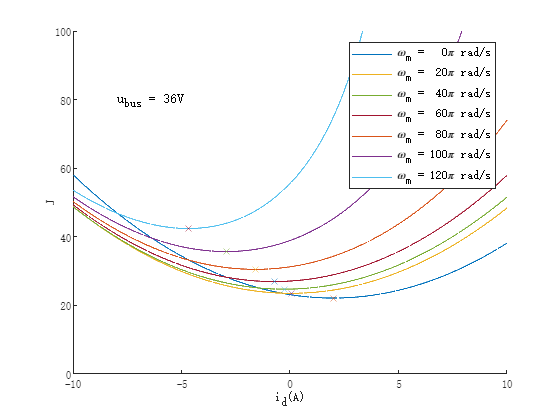

figure(1);
hold on;
Ubus = 36;
for w = 00*pi:20*pi:120*pi
    J = j(motor,Ubus,w,i);
    plot(i,J);
    [y,x] = findpeaks(-J,i);
    plot(x,-y,'x');
end
legend({'\omega_m =   0\pi rad/s','', ...
        '\omega_m =  20\pi rad/s','', ...
        '\omega_m =  40\pi rad/s','', ...
        '\omega_m =  60\pi rad/s','', ...
        '\omega_m =  80\pi rad/s','', ...
        '\omega_m = 100\pi rad/s','', ...
        '\omega_m = 120\pi rad/s',''}, 'FontSize', 8,'FontName', '宋体');
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('i_d(A)','Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
xlim([-10,10]);
xticks(-10:5:10); % 设置刻度

ylabel('J', 'Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
ylim([00,100]);
yticks(00:20:100); % 设置刻度
text(-8,80,'u_{bus} = 36V','FontName', '宋体');
box off;
hold off;

## 电压变化

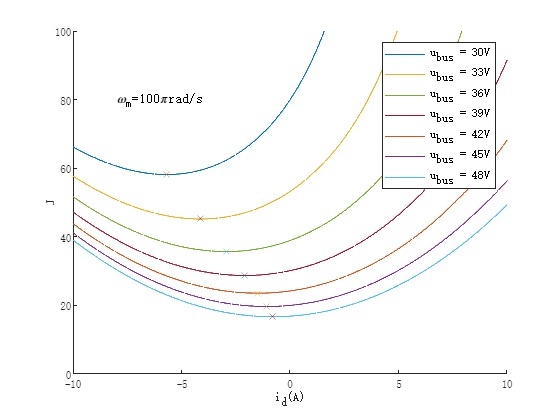

figure(2);
w = motor.radps_rated;
for Ubus = 30:3:48
    J = j(motor,Ubus,w,i);
    plot(i,J);
    hold on;
    [y,x] = findpeaks(-J,i);
    plot(x,-y,'x');
end
legend({'u_{bus} = 30V','', ...
        'u_{bus} = 33V','', ...
        'u_{bus} = 36V','', ...
        'u_{bus} = 39V','', ...
        'u_{bus} = 42V','', ...
        'u_{bus} = 45V','', ...
        'u_{bus} = 48V',''}, 'FontSize', 8,'FontName', '宋体');
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('i_d(A)','Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
xlim([-10,10]);
xticks(-10:5:10); % 设置刻度

ylabel('J', 'Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
ylim([00,100]);
yticks(00:20:100); % 设置刻度
text(-8,80,'\omega_m=100\pirad/s','FontName', '宋体');
box off;
hold off;

## 梯度下降法寻优

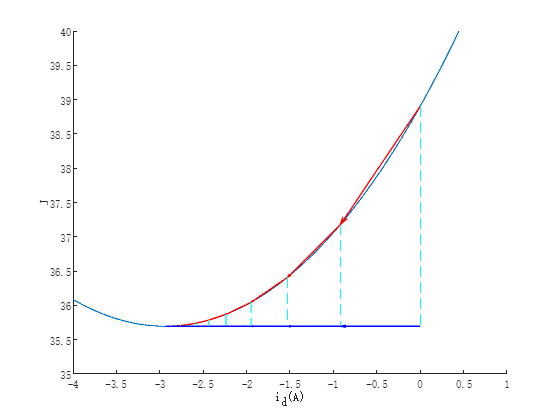

figure(3);
Ubus = 36;
w = motor.radps_rated;
J = j(motor,Ubus,w,i);

plot(i,J,'linewidth', 1);
hold on;
[y,x] = findpeaks(-J,i);
% plot(x,-y,'xb','linewidth', 2);

k = 5001;
l = 5001;
while(1)
    l = k + round((J(k+1)-J(k))*-100e3);
    if(l<1 || l>=10000)
        break;
    end
    if(xor(l<k, J(l)>J(k)))
        quiver(i(k),J(k),i(l)-i(k),J(l)-J(k),"off", '-r','LineWidth',1);
        quiver(i(k),-y,i(l)-i(k),0,"off", '-b','LineWidth',1);
        plot([i(k),i(k)],[J(k),-y],'--c');
        % plot([i(k),i(l)],[J(k),J(l)],'o-r');
        % PlotLineArrow(gca, [i(k),i(l)],[J(k),J(l)],'b','r');
        k = l;
    else
        break;
    end
end
set(gca, 'FontSize', 8,'FontName', '宋体');
xlabel('i_d(A)','Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
xlim([-4,1]);
% xticks(-10:5:10); % 设置刻度

ylabel('J', 'Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
ylim([35,40]);
% yticks(00:20:100); % 设置刻度
box off;
hold off;

## 最优电流曲线

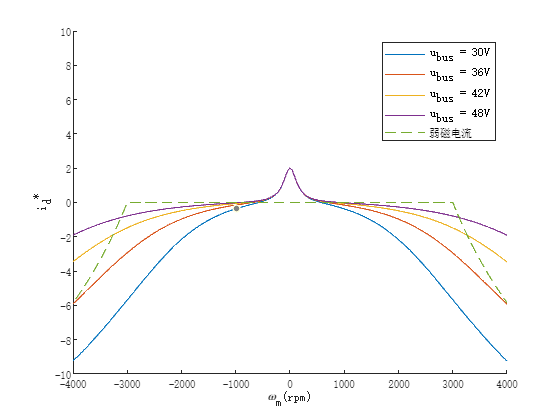

figure(4);
i_d = zeros(1000,1);
for Ubus = 30:6:48
    w = linspace(-1.5*motor.radps_rated,1.5*motor.radps_rated,1000);
    for s = 1:1000
        J = j(motor,Ubus,w(s),i);
        [y,x] = findpeaks(-J,i);
        i_d(s) = x(1);
    end
    plot(w*30/pi,i_d);
    hold on;
end
i_d = min(0,motor.psi*(motor.radps_rated./abs(w)-1))/motor.Ls;
plot(w*30/pi,i_d,'--');

set(gca, 'FontSize', 8,'FontName', '宋体');
legend({'u_{bus} = 30V'; ...
       % 'u_{bus} = 33V'; ...
        'u_{bus} = 36V'; ...
       % 'u_{bus} = 39V'; ...
        'u_{bus} = 42V'; ...
       % 'u_{bus} = 45V'; ...
        'u_{bus} = 48V'; ...
        '弱磁电流'}, 'FontSize', 8,'FontName', '宋体');
xlabel('\omega_m(rpm)','Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
xlim([-4000,4000]);

ylabel('{i_d}^*', 'Interpreter', 'tex', 'FontSize', 8,'FontName', '宋体');
ylim([-10,10]);
box off;
hold off;

function J = j(motor,Ubus,w,i)
    N = 1;
    Q = 0.25;
    R = 10000;
    w_mc = motor.radps_rated*0.05;
    J = -N*i*(w_mc^2/(w_mc^2+w^2)) +  Q*i.^2 + R./abs(Ubus^2/3-(motor.P*w)^2*(motor.psi+motor.Ls*i).^2);
end